# Multi-Period Distributed Optimal Power Flow

## Temporally Brute-Forced, Spatially Distributed, Integer-Relaxed NLP.

clearVars = true;
localUsername = getenv('USERNAME');
listOfUsernames = {'aryan', 'Aryan Ritwajeet Jha'};
if ismember(localUsername,  listOfUsernames)
    % For user 'aryan', change the current directory to the specified path
    cd(strcat("C:", filesep, "Users", filesep, localUsername, filesep, "Documents", filesep, ...
        "documents_general", filesep, "MultiPeriod-DistOPF-Benchmark", filesep) )
    addpath(genpath('functions\'))
    latex_interpreter
else
    fprintf("Are you not me? Might want to add the folder to the path or add folder to the workspace.\n");
end
addDirectories;

clearVariables(clearVars);

start = tic;
verbose = false;
logging = true;
logging_Aeq_beq = false;
systemName = 'ieee123'

systemName = 'ieee123'

objFunction = "gen_cost"

objFunction = "gen_cost"

numAreas = 4

numAreas = 4

T = 1

T = 1

macroItrMax = 100; % Max no. of permissible iterations for optimizing an area
noBatteries = true;
alpha = 1e-3;
% gamma = 1e-1;
gamma = 1e0;
DER_percent = 100;
Batt_percent = DER_percent;
delta_t = 1.00; % one hour
displayTables = true;
displayNetworkGraphs = false;
displayActualBusNumbersInGraphs = false;
saveNetworkGraphPlots = false;
generateTextFilesForResults = true;
displaySimulationResultPlots = false;
saveSimulationResultPlots = false;
saveSCDPlots = false;


% delta_t = 0.25; % 15 minutes = 0.25 hours
delta_t = 1.00;
% globalPVCoeff = 2.3;
globalPVCoeff = 1.0;
% lambdaVals = generateLoadProfile(T, 1.0, 1.1, 'upwards')
% lambdaVals = generateLoadProfile(T, 1.0, 1.4, 'upwards')
lambdaVals = generateLoadProfile(T, 1.0, 1.0, 'upwards')

lambdaVals = 1

loadVals = lambdaVals*3

loadVals = 3

% pvCoeffVals = globalPVCoeff*generatePVProfile(T, 0.8, 1.2, 0.9)
pvCoeffVals = globalPVCoeff*generatePVProfile(T, 1.0, 1.0, 1.0)

pvCoeffVals = 1


% costArray0 = [-1.0, 0.0, 0.7, 1.2, 1.5, 1.7, 6.4, 5.4, 2.5, 2.5, 3.2, 3.6, 2.2, 1.9, 1.8, 1.9, 2.9, 5.0, 4.6, 4.5, 4.4, 4.0, 2.8, 4.9]';
costArray0 = [1.6, 3.8, 1.7, 1.8, 2.1, 2.2, 2.4, 2.9, 4.4, 5.1, 4.3, 3.5, 2.8, 2.8, 2.3, 2.0, 2.3, 4.1, 3.4, 6.6, 4.7, 4.7, 5.0, 2.6]';
costArray = choose_middle_T_points(costArray0, T);

V_min = 0.95;
V_max = 1.05;
etta_C = 0.95;
etta_D = 0.95;
soc_min = 0.30;
soc_max = 0.95;

if numAreas == 1
    copf = true;
    myfprintf(verbose, logging, "Centralized OPF it is.");
    simNatureString = "Centralized-OPF";
else
    copf = false;
    myfprintf(verbose, logging, "Perforiming Distributed OPF with %d Areas.", numAreas);
    simNatureString = "Spatially-Distributed-OPF";
end


if strcmp(systemName, "ieee123")
    N = 128;
    m = N-1;
else
    error("Unknown Power System")
end

% actualBusNums = [1:36, 119, 126, 127, 117, 54:68, 122, 118, 37:53, 120, 125, 128, 69:116, 121, 123, 124]';
% N = max(actualBusNums);

if strcmp(objFunction, "loss_min")
    strObjectiveFunction = "Loss Minimization";
    suffixObj = "minLoss";
elseif strcmp(objFunction, "gen_cost")
    strObjectiveFunction = "Cost of Substation Power";
    suffixObj = "genCost";
else
    error("Objective Function NOT recognized.")
end

loggingLocationName = "logfiles/";

saveLocationFilename = strcat(loggingLocationName , systemName, "/numAreas_", num2str(numAreas), "/optimizationLogs.txt");
fileOpenedFlag = false;

systemDataFolder = strcat("rawData", filesep, systemName, filesep, "numAreas_", num2str(numAreas), filesep);

kVA_B = 1000; % base kVA
kV_B = 4.16/sqrt(3);  % 2.4018

a = [0.25 0.05]; %coefficient for correction step
chargeToPowerRatio = 4;

[CBMatrix, CBTable] = extractConnectionData(systemDataFolder);

numChildAreas = zeros(numAreas, 1);
numRelationships = length(CBTable.parentArea);
uniqueParents = unique(CBTable.parentArea);
numUniqueParents = length(uniqueParents);

[isLeaf, isRoot] = deal( ones(numAreas, 1) );
for relationshipNum = 1:numRelationships
    parAr = CBTable.parentArea(relationshipNum);
    isLeaf(parAr, 1) = 0;
    chAr = CBTable.childArea(relationshipNum);
    isRoot(chAr, 1) = 0;
    numChildAreas(parAr) = numChildAreas(parAr) + 1; %contains which area has how many children
end

sysInfo = struct();
sysInfo.N = N;
sysInfo.m = m;
sysInfo.numAreas = numAreas;
sysInfo.numChildAreas = numChildAreas; % An array of containing no. of 
% child areas for each area
sysInfo.systemName = systemName;
sysInfo.isLeaf = isLeaf;
sysInfo.isRoot = isRoot;
sysInfo.kVA_B = kVA_B;
sysInfo.kV_B = kV_B;
sysInfo.Battery.chargeToPowerRatio = chargeToPowerRatio;
sysInfo.CBTable = CBTable;
PLoss_allT_vs_macroItr = zeros(macroItrMax, 1);
PLoss_1toT_vs_macroItr = zeros(T, macroItrMax);
PSubs_allT_vs_macroItr = zeros(macroItrMax, 1);
PSubs_1toT_vs_macroItr = zeros(T, macroItrMax);
PSubsCost_allT_vs_macroItr = zeros(macroItrMax, 1);
PSubsCost_1toT_vs_macroItr = zeros(T, macroItrMax);

sysInfo.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;
sysInfo.PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
sysInfo.PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr;
sysInfo.PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr;
sysInfo.PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr;
sysInfo.PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr;

simInfo = struct();
simInfo.copf = copf;
simInfo.simNatureString = simNatureString;
simInfo.alpha = alpha;
simInfo.gamma = gamma;
simInfo.DER_percent = DER_percent;
simInfo.Batt_percent = Batt_percent;
simInfo.etta_C = etta_C;
simInfo.etta_D = etta_D;
simInfo.chargeToPowerRatio = chargeToPowerRatio;
simInfo.soc_min = soc_min;
simInfo.soc_max = soc_max;
simInfo.V_min = V_min;
simInfo.V_max = V_max;
simInfo.lambdaVals = lambdaVals;
simInfo.pvCoeffVals = pvCoeffVals;
simInfo.noBatteries = noBatteries;
simInfo.objFunction = objFunction;
simInfo.strObjectiveFunction = strObjectiveFunction;
simInfo.suffixObj = suffixObj;
simInfo.T = T;
if copf
    simInfo.alg.spatial = "CentralizedOPF";
else
    simInfo.alg.spatial = "ENApp";
end
simInfo.costArray = costArray;
simInfo.delta_t = delta_t;
simInfo.alg.temporal = "BruteForce";
simInfo.alg.macroItrMax = macroItrMax;
% stopping criterion
macroItrResidualTolerance = 0.001 ; % Tolerance

simInfo.alg.macroItrResidualTolerance = macroItrResidualTolerance;
simInfo.macroItrsCompleted = 0;
simInfo.alg.correctionStep = a;
simInfo.macroItr = 0;

simInfo.alg.microItrMax = 100;
simInfo.alg.tolfun = 1e-6;
simInfo.alg.stepTol = 1e-6;
simInfo.alg.constraintTol = 1e-6;
simInfo.alg.optimalityTol = 1e-6;

maxConnectingBusNum = max(CBTable.conBus_parentAreaTo);


#### Start with the algorithm

if logging && verbose
    error("Kindly specify ONLY one of the following arguments as true: verbose and logging.")
elseif logging && ~verbose
    fileOpenedFlag = true;
    fid = fopen(saveLocationFilename, 'w');
elseif ~logging
    logging = verbose;
    fid = 1;
else
    fid = 1;
end

myfprintf(true, fid, "A total of %d time-periods (of %d minutes each, so %.2f hours in total) " + ...
"will be run.\n", T, delta_t*60, delta_t*T);

myfprintf(logging, fid, "********Running Full OPF for the system.********\n"); %always true
keepRunningIterations = true;
time_dist = zeros(macroItrMax, numAreas);

maxResidual_vs_macroItr_allT = zeros(macroItrMax, 1);
v1_1 = 1.03^2*ones(numAreas, 1);
v1_1toT = repmat(v1_1, 1, T);

Se_iter = zeros(macroItrMax, numAreas, T);
% Se_iter = zeros(macroItrMax, m, numAreas, T);
V_iter = zeros(macroItrMax, N, numUniqueParents, T);
S12_allRelationships = CBTable.S_childArea;
S12_allRelationships_1toT = repmat(S12_allRelationships, 1, T);
S_parent_1toT = zeros(numAreas, T);
S_Areas_1toT = zeros(N, numAreas, T);
v_Areas_1toT = zeros(N, numAreas, T);
% v1_1toT_vs_macroItr = zeros(numAreas, T, macroItrMax);
v1_1toT_vs_macroItr = zeros(numRelationships, T, macroItrMax);
S12_1toT_vs_macroItr = zeros(numRelationships, T, macroItrMax);
Residuals_1toT_vs_macroItr = zeros(2*numRelationships, T, macroItrMax);

while keepRunningIterations
    for Area = 1:numAreas
    % for Area = 1
    % for Area = [2 3 1 4]
        macroItr = simInfo.macroItr;
        myfprintf(true, "Macro-iteration %d: Running OPF for Area %d.\n", macroItr+1, Area);

        v_parAr_1toT = v1_1toT(Area, 1:T)
        S_chArs_1toT = S12_allRelationships_1toT(CBTable.parentArea == Area, 1:T)

        if macroItr == 0
            areaInfo.Area = Area;
        else
            areaInfo = sysInfo.Area{Area};
        end

        [xVals_Area, sysInfo, simInfo, ...
            time_dist] = ...
            ...
            NL_OPF_dist2(sysInfo, simInfo, areaInfo, v_parAr_1toT, S_chArs_1toT, ...
            time_dist, 'verbose', verbose, 'saveToFile', true, 'logging', logging, ...
            'saveSCDPlots', saveSCDPlots);
        
        nVars1_Area = length(xVals_Area)/T;
        xVals_Area_1toT = reshape(xVals_Area, nVars1_Area, T)
        % macroItr = simInfo.macroItr;
        
        myfprintf(true, fid, "Current Macro-iteration %d: OPF for Area %d computed.\n", macroItr+1, Area)
        areaInfo = sysInfo.Area{Area};
        N_Area = areaInfo.N_Area;
        m_Area = areaInfo.m_Area;
    
        % indices_Pij = areaInfo.indices_Pij;
        P_Area_1toT = xVals_Area(areaInfo.indices_Pij)'; %m_Areax1
        Q_Area_1toT = xVals_Area(areaInfo.indices_Qij)'; %m_Areax1
        S_Area_1toT = complex(P_Area_1toT, Q_Area_1toT); %m_Areax1
        vAll_Area_1toT = xVals_Area(areaInfo.indices_vAllj)'; %N_Areax1
        
        PSubs_Area_1toT = P_Area_1toT(1, 1:T);
        S_parent_1toT(Area, 1:T) = S_Area_1toT(1, 1:T);

        v_Areas_1toT(1:N_Area, Area, 1:T) = vAll_Area_1toT;
        S_Areas_1toT(1:m_Area, Area, 1:T) = S_Area_1toT;  % Storing all the S flow of the Area
        
        PLoss_allT_vs_macroItr(macroItr+1) = PLoss_allT_vs_macroItr(macroItr+1) + areaInfo.PLoss_allT;
        PLoss_1toT_vs_macroItr(1:T, macroItr+1) = PLoss_1toT_vs_macroItr(1:T, macroItr+1) + areaInfo.PLoss_1toT;
        PSubs_allT_vs_macroItr(macroItr+1) = PSubs_allT_vs_macroItr(macroItr+1) + areaInfo.PSubs_allT;
        PSubs_1toT_vs_macroItr(1:T, macroItr+1) = PSubs_1toT_vs_macroItr(1:T, macroItr+1) + areaInfo.PSubs_1toT;
        PSubsCost_allT_vs_macroItr(macroItr+1) = PSubsCost_allT_vs_macroItr(macroItr+1) + areaInfo.PSubsCost_allT;
        PSubsCost_1toT_vs_macroItr(1:T, macroItr+1) = PSubsCost_1toT_vs_macroItr(1:T, macroItr+1) + areaInfo.PSubsCost_1toT;

        sysInfo.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;  
        sysInfo.Ploss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
        sysInfo.PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr;
        sysInfo.PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr;
        sysInfo.PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr;
        sysInfo.PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr;
        % keyboard
    end
    
    myfprintf(true, "Macro-iteration %d: OPF's for all Areas completed. Checking for convergence.\n", macroItr+1);
    % first let's quickly compute system losses for the macroItr first and
    % store them
    
    if ~copf
        for relationshipNum = 1 : numRelationships
    
            parAr = CBTable.parentArea(relationshipNum);
            chAr = CBTable.childArea(relationshipNum);
            myfprintf(true, "Checking for convergence between parent Area %d and child Area %d\n", parAr, chAr);

            parentAreaConnectingBus = CBTable.conBus_parentAreaTo(relationshipNum);
            S12_fromParent_1toT = reshape(S_Areas_1toT(parentAreaConnectingBus - 1, parAr, 1:T), 1, T)
            S12_intoChild_1toT = reshape(S_parent_1toT(chAr, 1:T), 1, T)
    
            delta_S12_1toT = S12_fromParent_1toT - S12_intoChild_1toT
    
            v_parentSide_1toT = reshape(v_Areas_1toT(parentAreaConnectingBus, parAr, 1:T), 1, T);
            v_childSide_1toT = v1_1toT(chAr, 1:T);
    
            v1_1toT_vs_macroItr(relationshipNum, 1:T, macroItr+1) = v_parentSide_1toT;
            S12_1toT_vs_macroItr(relationshipNum, 1:T, macroItr+1) = S12_intoChild_1toT;

            delta_v_1toT = v_parentSide_1toT - v_childSide_1toT
    
            Residual_Area_1toT = reshape([delta_S12_1toT; delta_v_1toT], 2*T, 1);
            
            [currentMaxResidual_1toT, lin_idx] = max(abs(Residual_Area_1toT));

            row = lin_idx;
            myfprintf(true, "Macro-iteration %d: Current Biggest Residual is %d at index %d.\n", macroItr+1, currentMaxResidual_1toT, row);

            
            if currentMaxResidual_1toT > maxResidual_vs_macroItr_allT(macroItr+1)
                maxResidual_vs_macroItr_allT(macroItr+1) = currentMaxResidual_1toT;
                myfprintf(true, "It is even bigger than the previous biggest residual.\n");
            end
    
        end
        
        myfprintf(true, "Macro-iteration %d: Checking for convergence among all connected areas completed.\n", macroItr+1);
        if macroItr == macroItrMax - 1
            error("Didn't converge even after %d macro-iterations, terminating.\n", macroItrMax);
    
        elseif currentMaxResidual_1toT < macroItrResidualTolerance
            myfprintf(true, "MPOPF for Horizon T = %d Converged in %d macro-iterations!\n", T, macroItr+1);
            keepRunningIterations = false;
            maxResidual_vs_macroItr_allT = maxResidual_vs_macroItr_allT(1:macroItr+1);
    
        else
            myfprintf(true, "MPOPF for Horizon T = %d , Still yet to converge after %d macro-iterations, continuing.\n", T, macroItr+1)
            %Communication-
            myfprintf(true, "Since there is still a difference in boundary variables, " + ...
                "let's exchange boundary variables.\n")

            for relationshipNum = 1:numRelationships
                parAr = CBTable.parentArea(relationshipNum);
                chAr = CBTable.childArea(relationshipNum);
                myfprintf(true, "Communicating between parent Area %d and child Area %d\n", parAr, chAr);

                busParTo = CBTable.conBus_parentAreaTo(relationshipNum);

                areaInfo_par = sysInfo.Area{parAr};
                areaInfo_ch = sysInfo.Area{chAr};
    
                
                V_iter(macroItr+1, busParTo, parAr, 1:T) = v_Areas_1toT(busParTo, parAr, 1:T) ;

                Se_iter(macroItr+1, chAr, 1:T) = S_parent_1toT(chAr, 1:T);
    
                if macroItr >= 2
                    myfprintf(true, "***Macro-iteration %d Communication Voltage:****\n", macroItr+1)
                    v1_1toT(chAr, 1:T) = a(2)*reshape(V_iter(macroItr-1, busParTo, parAr, 1:T), 1, T) + ...
                        a(1)*reshape(V_iter(macroItr, busParTo, parAr, 1:T), 1, T) + ...
                        (1-sum(a))*reshape(v_Areas_1toT(busParTo, parAr, 1:T), 1, T)
                    disp(v1_1toT(char, 1:T))

                    myfprintf(true, "***Macro-iteration %d Communication Power:****\n", macroItr+1)

                    S12_allRelationships_1toT(relationshipNum, 1:T) = a(2)*reshape(Se_iter(macroItr-1, chAr, 1:T), 1, T)+...
                        a(1)*reshape(Se_iter(macroItr, chAr, 1:T), 1, T)+...
                        (1-sum(a))*S_parent_1toT(chAr, 1:T);
                    disp(S12_allRelationships_1toT(relationshipNum, 1:T));
                else
                    myfprintf(true, "***Macro-iteration %d Communication Voltage:****\n", macroItr+1)
                    v1_1toT(chAr, 1:T) = v_Areas_1toT(busParTo, parAr, 1:T)
                    disp(v1_1toT(chAr, 1:T))

                    myfprintf(true, "***Macro-iteration %d Communication Power:****\n", macroItr+1)
                    S12_allRelationships_1toT(relationshipNum, 1:T) = S_parent_1toT(chAr, 1:T)
                    disp(S12_allRelationships_1toT(relationshipNum, 1:T));

    
                end
    
            end

            simInfo.macroItr = macroItr + 1;

        end

        
    else
        keepRunningIterations = false;
        myfprintf(verbose, "Centralized MPOPF for %d Horizons ended.\n", T);
    end

end

Macro-iteration 1: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =      0
     0


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         185    0.000000e+00     6.090e-02     1.000e+00     0.000e+00     3.500e+03  
    1         391    3.218485e-01     6.087e-02     5.585e-04     2.773e-04     3.498e+03  
    2         577    4.034554e+02     1.826e-02     7.000e-01     3.473e-01     1.049e+03  
    3         762    5.770352e+02     1.969e-02     1.000e+00     3.386e-01     3.995e+00  
    4         947    5.766993e+02     2.466e-02     1.000e+00     2.934e-01     2.039e+00  
    5        1132    5.771383e+02     4.447e-03     1.000e+00     1.556e-01     3.611e+00  
    6        1317    5.771060e+02     4.142e-03     1.000e+00     1.274e-01     3.535e+00  
    7        1502    5.772320e+02     9.795e-04     1.000e+00     9.218e-02     1.390e+00  
    8        1689    5.773039e+02     7.419e-04     7.000e-01     9.545e-02     1.

xVals_Area_1toT =     0.1649
    0.1649
    0.0043
    0.0217
    0.0087
    0.0130
    0.0087
    0.1302
    0.1258
    0.0217


Macro-iteration 1: Running OPF for Area 2.


v_parAr_1toT = 1.0609

S_chArs_1toT = 0

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          86    0.000000e+00     6.090e-02     1.000e+00     0.000e+00     3.500e+03  
    1         193    2.329496e-01     6.087e-02     5.585e-04     2.149e-04     3.498e+03  
    2         279    4.170657e+02     1.428e-02     1.000e+00     3.845e-01     5.107e+00  
    3         365    4.180597e+02     8.308e-03     1.000e+00     2.227e-01     3.476e+00  
    4         452    4.182486e+02     1.443e-03     1.000e+00     2.306e-01     2.184e+00  
    5         539    4.182947e+02     1.249e-03     1.000e+00     1.188e-01     5.474e+00  
    6         627    4.181848e+02     4.832e-04     7.000e-01     7.577e-02     1.844e+00  
    7         714    4.181936e+02     3.904e-04     1.000e+00     7.928e-02     1.972e+00  
    8         802    4.181984e+02     2.042e-04     7.000e-01     6.731e-02     4.

xVals_Area_1toT =     0.1195
    0.1195
    0.1108
    0.1021
    0.0087
    0.0043
    0.0934
    0.0087
    0.0043
    0.0847


Macro-iteration 1: Running OPF for Area 3.


v_parAr_1toT = 1.0609


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          92    0.000000e+00     6.090e-02     1.000e+00     0.000e+00     3.500e+03  
    1         206    2.238467e-01     6.088e-02     3.910e-04     1.719e-04     3.499e+03  
    2         298    5.725250e+02     2.686e-02     1.000e+00     4.394e-01     4.426e+00  
    3         390    5.733410e+02     8.229e-03     1.000e+00     1.987e-01     2.157e+00  
    4         482    5.732076e+02     7.974e-03     1.000e+00     1.804e-01     9.214e-01  
    5         574    5.733690e+02     4.009e-03     1.000e+00     1.156e-01     1.230e+00  
    6         666    5.733768e+02     2.072e-03     1.000e+00     8.939e-02     1.169e+00  
    7         759    5.734633e+02     6.038e-04     1.000e+00     1.175e-01     3.146e+00  
    8         852    5.733999e+02     3.732e-04     1.000e+00     1.006e-01     8.

xVals_Area_1toT =     0.1638
    0.1638
    0.0173
    0.0087
    0.0087
    0.0043
    0.1377
    0.0043
    0.1334
    0.0087


Macro-iteration 1: Running OPF for Area 4.


v_parAr_1toT = 1.0609


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         250    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.500e+03  
    1         521    6.034859e-01     1.966e-01     5.585e-04     4.663e-04     3.498e+03  
    2         773    5.297347e+02     1.002e-01     4.900e-01     4.088e-01     1.784e+03  
    3        1023    1.083058e+03     3.062e-02     1.000e+00     5.118e-01     3.606e+00  
    4        1273    1.083275e+03     3.036e-02     1.000e+00     3.617e-01     3.128e+00  
    5        1523    1.083595e+03     2.467e-02     1.000e+00     3.717e-01     2.345e+00  
    6        1773    1.083560e+03     1.827e-02     1.000e+00     2.643e-01     3.329e+00  
    7        2025    1.083576e+03     9.332e-03     4.900e-01     1.575e-01     1.421e+00  
    8        2275    1.083774e+03     5.012e-03     1.000e+00     1.894e-01     4.

xVals_Area_1toT =     0.3097
    0.3097
    0.3097
    0.0260
    0.0217
    0.0130
    0.0087
    0.1880
    0.0260
    0.0173


Macro-iteration 1: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 3.6709e-20 + 1.4625e-20i

S12_intoChild_1toT = 0.1195 - 0.0005i

delta_S12_1toT = -0.1195 + 0.0005i

delta_v_1toT = -0.0034

Macro-iteration 1: Current Biggest Residual is 1.194879e-01 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = -3.2575e-20 + 6.1405e-22i

S12_intoChild_1toT = 0.1638 - 0.0003i

delta_S12_1toT = -0.1638 + 0.0003i

delta_v_1toT = -0.0047

Macro-iteration 1: Current Biggest Residual is 1.638324e-01 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 8.4651e-21 - 1.7922e-19i

S12_intoChild_1toT = 0.3097 - 0.0011i

delta_S12_1toT = -0.3097 + 0.0011i

delta_v_1toT = -0.0036

Macro-iteration 1: Current Biggest Residual is 3.097104e-01 at index 1.


It is even bigger than the previous biggest residual.


Macro-iteration 1: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 1 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609
    1.0575
    1.0609
    1.0609


    1.0575



***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.1195 - 0.0005i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


   0.1195 - 0.0005i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609
    1.0575
    1.0562
    1.0609


    1.0562



***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.1195 - 0.0005i
   0.1638 - 0.0003i
   0.0000 + 0.0000i


   0.1638 - 0.0003i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609
    1.0575
    1.0562
    1.0573


    1.0573



***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.1195 - 0.0005i
   0.1638 - 0.0003i
   0.3097 - 0.0011i


   0.3097 - 0.0011i



Macro-iteration 2: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.1195 - 0.0005i
   0.1638 - 0.0003i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         185    0.000000e+00     1.638e-01     1.000e+00     0.000e+00     3.500e+03  
    1         394    3.003692e-01     1.638e-01     1.916e-04     2.010e-04     3.499e+03  
    2         584    2.637577e+02     1.363e-01     1.681e-01     1.763e-01     2.911e+03  
    3         773    5.775393e+02     1.036e-01     2.401e-01     2.193e-01     2.212e+03  
    4         963    7.448096e+02     8.615e-02     1.681e-01     1.584e-01     1.840e+03  
    5        1151    1.029210e+03     5.660e-02     3.430e-01     2.345e-01     1.209e+03  
    6        1336    1.575541e+03     2.698e-02     1.000e+00     4.641e-01     4.261e+00  
    7        1521    1.576380e+03     3.992e-03     1.000e+00     1.582e-01     3.696e+00  
    8        1706    1.576579e+03     7.269e-04     1.000e+00     9.164e-02     2.

xVals_Area_1toT =     0.4505
    0.4505
    0.0043
    0.0217
    0.0087
    0.0130
    0.0087
    0.4150
    0.4102
    0.0217


Macro-iteration 2: Running OPF for Area 2.


v_parAr_1toT = 1.0575

S_chArs_1toT = 0.3097 - 0.0011i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          86    0.000000e+00     3.097e-01     1.000e+00     0.000e+00     3.500e+03  
    1         196    2.875719e-01     3.096e-01     1.916e-04     2.088e-04     3.499e+03  
    2         287    2.525205e+02     2.576e-01     1.681e-01     1.832e-01     2.911e+03  
    3         377    5.531138e+02     1.958e-01     2.401e-01     2.232e-01     2.212e+03  
    4         467    7.821801e+02     1.488e-01     2.401e-01     2.103e-01     1.681e+03  
    5         555    1.138228e+03     7.586e-02     4.900e-01     3.162e-01     8.573e+02  
    6         641    1.510993e+03     1.750e-02     1.000e+00     4.170e-01     5.808e+00  
    7         727    1.511179e+03     6.446e-03     1.000e+00     2.051e-01     1.513e+00  
    8         813    1.511782e+03     1.964e-03     1.000e+00     1.050e-01     3.

xVals_Area_1toT =     0.4320
    0.4320
    0.4226
    0.4136
    0.0087
    0.0043
    0.4047
    0.0087
    0.0043
    0.3955


Macro-iteration 2: Running OPF for Area 3.


v_parAr_1toT = 1.0562


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          92    0.000000e+00     5.616e-02     1.000e+00     0.000e+00     3.500e+03  
    1         206    2.238467e-01     5.614e-02     3.910e-04     1.671e-04     3.499e+03  
    2         298    5.725250e+02     2.685e-02     1.000e+00     4.272e-01     4.272e+00  
    3         390    5.733487e+02     7.993e-03     1.000e+00     1.964e-01     2.136e+00  
    4         482    5.732144e+02     7.939e-03     1.000e+00     1.790e-01     8.814e-01  
    5         574    5.733725e+02     4.009e-03     1.000e+00     1.159e-01     1.239e+00  
    6         666    5.733808e+02     2.072e-03     1.000e+00     8.996e-02     1.162e+00  
    7         759    5.734671e+02     6.038e-04     1.000e+00     1.207e-01     3.132e+00  
    8         852    5.734057e+02     3.732e-04     1.000e+00     9.951e-02     8.

xVals_Area_1toT =     0.1638
    0.1638
    0.0173
    0.0087
    0.0087
    0.0043
    0.1377
    0.0043
    0.1334
    0.0087


Macro-iteration 2: Running OPF for Area 4.


v_parAr_1toT = 1.0573


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         250    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.500e+03  
    1         521    6.034859e-01     1.966e-01     5.585e-04     4.591e-04     3.498e+03  
    2         773    5.297347e+02     1.002e-01     4.900e-01     4.026e-01     1.784e+03  
    3        1023    1.083067e+03     3.013e-02     1.000e+00     5.026e-01     3.578e+00  
    4        1273    1.083316e+03     2.905e-02     1.000e+00     3.534e-01     3.082e+00  
    5        1523    1.083617e+03     2.219e-02     1.000e+00     3.551e-01     2.311e+00  
    6        1773    1.083573e+03     1.868e-02     1.000e+00     2.708e-01     4.718e+00  
    7        2024    1.084083e+03     6.262e-03     1.000e+00     3.427e-01     6.506e+00  
    8        2275    1.083963e+03     7.213e-04     1.000e+00     2.526e-01     2.

xVals_Area_1toT =     0.3097
    0.3097
    0.3097
    0.0260
    0.0217
    0.0130
    0.0087
    0.1880
    0.0260
    0.0173


Macro-iteration 2: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.1195 - 0.0005i

S12_intoChild_1toT = 0.4320 - 0.0050i

delta_S12_1toT = -0.3125 + 0.0045i

delta_v_1toT = -0.0067

Macro-iteration 2: Current Biggest Residual is 3.125007e-01 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1638 - 0.0003i

S12_intoChild_1toT = 0.1638 - 0.0003i

delta_S12_1toT = -6.9732e-07 + 5.5440e-05i

delta_v_1toT = -0.0094

Macro-iteration 2: Current Biggest Residual is 9.443049e-03 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.3097 - 0.0011i

S12_intoChild_1toT = 0.3097 - 0.0011i

delta_S12_1toT = -1.8032e-06 + 1.5210e-05i

delta_v_1toT = -0.0147

Macro-iteration 2: Current Biggest Residual is 1.465762e-02 at index 2.


Macro-iteration 2: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 2 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 2 Communication Voltage:****


v1_1toT =     1.0609
    1.0507
    1.0562
    1.0573


    1.0507



***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT =    0.4320 - 0.0050i
   0.1638 - 0.0003i
   0.3097 - 0.0011i


   0.4320 - 0.0050i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 2 Communication Voltage:****


v1_1toT =     1.0609
    1.0507
    1.0467
    1.0573


    1.0467



***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT =    0.4320 - 0.0050i
   0.1638 - 0.0003i
   0.3097 - 0.0011i


   0.1638 - 0.0003i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 2 Communication Voltage:****


v1_1toT =     1.0609
    1.0507
    1.0467
    1.0427


    1.0427



***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT =    0.4320 - 0.0050i
   0.1638 - 0.0003i
   0.3097 - 0.0011i


   0.3097 - 0.0011i



Macro-iteration 3: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.4320 - 0.0050i
   0.1638 - 0.0003i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         185    0.000000e+00     4.320e-01     1.000e+00     0.000e+00     3.500e+03  
    1         395    3.569238e-01     4.319e-01     1.341e-04     2.343e-04     3.500e+03  
    2         587    2.195130e+02     3.963e-01     8.235e-02     1.439e-01     3.211e+03  
    3         778    5.072599e+02     3.497e-01     1.176e-01     1.909e-01     2.834e+03  
    4         969    7.616690e+02     3.086e-01     1.176e-01     1.799e-01     2.500e+03  
    5        1159    1.082906e+03     2.567e-01     1.681e-01     2.342e-01     2.080e+03  
    6        1349    1.350803e+03     2.136e-01     1.681e-01     2.339e-01     1.730e+03  
    7        1538    1.669648e+03     1.623e-01     2.401e-01     2.710e-01     1.315e+03  
    8        1725    2.165563e+03     8.276e-02     4.900e-01     4.532e-01     6.

xVals_Area_1toT =     0.7671
    0.7671
    0.0043
    0.0217
    0.0087
    0.0130
    0.0087
    0.7302
    0.7244
    0.0217


Macro-iteration 3: Running OPF for Area 2.


v_parAr_1toT = 1.0507

S_chArs_1toT = 0.3097 - 0.0011i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          86    0.000000e+00     3.097e-01     1.000e+00     0.000e+00     3.500e+03  
    1         196    2.875742e-01     3.097e-01     1.916e-04     2.079e-04     3.499e+03  
    2         287    2.525225e+02     2.576e-01     1.681e-01     1.823e-01     2.911e+03  
    3         377    5.531196e+02     1.958e-01     2.401e-01     2.220e-01     2.212e+03  
    4         467    7.821948e+02     1.488e-01     2.401e-01     2.096e-01     1.681e+03  
    5         555    1.138258e+03     7.587e-02     4.900e-01     3.152e-01     8.573e+02  
    6         641    1.511064e+03     1.753e-02     1.000e+00     4.164e-01     5.764e+00  
    7         727    1.511257e+03     6.445e-03     1.000e+00     2.029e-01     1.364e+00  
    8         813    1.511861e+03     2.268e-03     1.000e+00     1.095e-01     2.

xVals_Area_1toT =     0.4320
    0.4320
    0.4226
    0.4136
    0.0087
    0.0043
    0.4047
    0.0087
    0.0043
    0.3955


Macro-iteration 3: Running OPF for Area 3.


v_parAr_1toT = 1.0467


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          92    0.000000e+00     5.000e-02     1.000e+00     0.000e+00     3.500e+03  
    1         206    2.238467e-01     4.998e-02     3.910e-04     1.585e-04     3.499e+03  
    2         299    4.008346e+02     1.499e-02     7.000e-01     2.836e-01     1.050e+03  
    3         391    5.733130e+02     8.578e-03     1.000e+00     2.225e-01     1.998e+00  
    4         483    5.731610e+02     9.100e-03     1.000e+00     1.988e-01     7.863e-01  
    5         575    5.733814e+02     4.005e-03     1.000e+00     1.210e-01     1.101e+00  
    6         667    5.733788e+02     2.073e-03     1.000e+00     9.253e-02     1.081e+00  
    7         759    5.734019e+02     6.392e-04     1.000e+00     7.365e-02     1.279e+00  
    8         852    5.734628e+02     9.189e-04     1.000e+00     1.436e-01     1.

xVals_Area_1toT =     0.1638
    0.1638
    0.0173
    0.0087
    0.0087
    0.0043
    0.1377
    0.0043
    0.1334
    0.0087


Macro-iteration 3: Running OPF for Area 4.


v_parAr_1toT = 1.0427


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         250    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.500e+03  
    1         522    4.224401e-01     1.966e-01     3.910e-04     3.035e-04     3.499e+03  
    2         774    5.296418e+02     1.003e-01     4.900e-01     3.802e-01     1.784e+03  
    3        1024    1.083102e+03     2.867e-02     1.000e+00     4.691e-01     3.466e+00  
    4        1274    1.083459e+03     2.513e-02     1.000e+00     3.306e-01     2.948e+00  
    5        1524    1.083677e+03     1.930e-02     1.000e+00     3.391e-01     2.407e+00  
    6        1774    1.083760e+03     1.796e-02     1.000e+00     2.452e-01     2.242e+00  
    7        2024    1.083743e+03     5.450e-03     1.000e+00     1.822e-01     2.510e+00  
    8        2274    1.083819e+03     1.784e-03     1.000e+00     1.486e-01     2.

xVals_Area_1toT =     0.3097
    0.3097
    0.3097
    0.0260
    0.0217
    0.0130
    0.0087
    0.1880
    0.0260
    0.0173


Macro-iteration 3: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.4320 - 0.0049i

S12_intoChild_1toT = 0.4320 - 0.0050i

delta_S12_1toT = -2.0446e-05 + 4.6650e-05i

delta_v_1toT = -0.0074

Macro-iteration 3: Current Biggest Residual is 7.399027e-03 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1638 - 0.0003i

S12_intoChild_1toT = 0.1638 - 0.0003i

delta_S12_1toT = -1.8603e-06 + 1.4187e-06i

delta_v_1toT = -0.0074

Macro-iteration 3: Current Biggest Residual is 7.383585e-03 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.3097 - 0.0011i

S12_intoChild_1toT = 0.3097 - 0.0011i

delta_S12_1toT = -1.2627e-05 + 7.6176e-06i

delta_v_1toT = -0.0067

Macro-iteration 3: Current Biggest Residual is 6.740862e-03 at index 2.


Macro-iteration 3: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 3 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 3 Communication Voltage:****


v1_1toT =     1.0609
    1.0459
    1.0467
    1.0427


***Macro-iteration 3 Communication Power:****


   0.4163 - 0.0048i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 3 Communication Voltage:****


v1_1toT =     1.0609
    1.0459
    1.0420
    1.0427


***Macro-iteration 3 Communication Power:****


   0.1638 - 0.0003i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 3 Communication Voltage:****


v1_1toT =     1.0609
    1.0459
    1.0420
    1.0387


***Macro-iteration 3 Communication Power:****


   0.3097 - 0.0011i



Macro-iteration 4: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.4163 - 0.0048i
   0.1638 - 0.0003i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         185    0.000000e+00     4.163e-01     1.000e+00     0.000e+00     3.500e+03  
    1         395    3.495990e-01     4.163e-01     1.341e-04     2.295e-04     3.500e+03  
    2         587    2.150082e+02     3.820e-01     8.235e-02     1.409e-01     3.211e+03  
    3         778    4.968416e+02     3.371e-01     1.176e-01     1.869e-01     2.834e+03  
    4         969    7.460120e+02     2.974e-01     1.176e-01     1.763e-01     2.500e+03  
    5        1159    1.060623e+03     2.474e-01     1.681e-01     2.289e-01     2.080e+03  
    6        1349    1.322984e+03     2.058e-01     1.681e-01     2.282e-01     1.730e+03  
    7        1538    1.635228e+03     1.564e-01     2.401e-01     2.640e-01     1.315e+03  
    8        1725    2.120853e+03     7.977e-02     4.900e-01     4.400e-01     6.

xVals_Area_1toT =     0.7512
    0.7512
    0.0043
    0.0217
    0.0087
    0.0130
    0.0087
    0.7144
    0.7086
    0.0217


Macro-iteration 4: Running OPF for Area 2.


v_parAr_1toT = 1.0459

S_chArs_1toT = 0.3097 - 0.0011i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          86    0.000000e+00     3.097e-01     1.000e+00     0.000e+00     3.500e+03  
    1         196    2.875808e-01     3.097e-01     1.916e-04     2.073e-04     3.499e+03  
    2         288    1.768560e+02     2.732e-01     1.176e-01     1.273e-01     3.088e+03  
    3         379    3.998367e+02     2.273e-01     1.681e-01     1.625e-01     2.569e+03  
    4         470    5.857380e+02     1.891e-01     1.681e-01     1.610e-01     2.137e+03  
    5         560    8.070650e+02     1.437e-01     2.401e-01     1.798e-01     1.624e+03  
    6         648    1.151392e+03     7.329e-02     4.900e-01     2.926e-01     8.282e+02  
    7         734    1.511086e+03     2.095e-02     1.000e+00     3.886e-01     3.431e+00  
    8         820    1.511581e+03     3.338e-03     1.000e+00     1.838e-01     5.

xVals_Area_1toT =     0.4320
    0.4320
    0.4226
    0.4136
    0.0087
    0.0043
    0.4047
    0.0087
    0.0043
    0.3955


Macro-iteration 4: Running OPF for Area 3.


v_parAr_1toT = 1.0420


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          92    0.000000e+00     5.000e-02     1.000e+00     0.000e+00     3.500e+03  
    1         206    2.238467e-01     4.998e-02     3.910e-04     1.547e-04     3.499e+03  
    2         299    4.008346e+02     1.499e-02     7.000e-01     2.768e-01     1.050e+03  
    3         391    5.733188e+02     7.788e-03     1.000e+00     2.153e-01     1.874e+00  
    4         484    5.734491e+02     5.233e-04     1.000e+00     1.923e-01     1.076e+00  
    5         578    5.734254e+02     4.781e-04     7.000e-01     8.595e-02     3.961e-01  
    6         671    5.734474e+02     2.804e-04     1.000e+00     7.962e-02     9.986e-01  
    7         765    5.734334e+02     2.088e-04     7.000e-01     5.839e-02     6.734e-01  
    8         859    5.735230e+02     1.056e-04     7.000e-01     1.581e-01     1.

xVals_Area_1toT =     0.1638
    0.1638
    0.0173
    0.0087
    0.0087
    0.0043
    0.1377
    0.0043
    0.1334
    0.0087


Macro-iteration 4: Running OPF for Area 4.


v_parAr_1toT = 1.0387


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         250    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.500e+03  
    1         522    4.224401e-01     1.966e-01     3.910e-04     2.994e-04     3.499e+03  
    2         774    5.296418e+02     1.003e-01     4.900e-01     3.751e-01     1.784e+03  
    3        1024    1.083112e+03     2.815e-02     1.000e+00     4.599e-01     3.432e+00  
    4        1274    1.083493e+03     2.344e-02     1.000e+00     3.237e-01     2.940e+00  
    5        1524    1.083686e+03     1.605e-02     1.000e+00     3.326e-01     2.429e+00  
    6        1774    1.083805e+03     5.590e-03     1.000e+00     1.648e-01     2.438e+00  
    7        2027    1.083806e+03     4.081e-03     3.430e-01     7.267e-02     1.032e+00  
    8        2278    1.083894e+03     1.798e-03     7.000e-01     1.069e-01     1.

xVals_Area_1toT =     0.3097
    0.3097
    0.3097
    0.0260
    0.0217
    0.0130
    0.0087
    0.1880
    0.0260
    0.0173


Macro-iteration 4: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.4164 - 0.0048i

S12_intoChild_1toT = 0.4320 - 0.0050i

delta_S12_1toT = -0.0157 + 0.0002i

delta_v_1toT = -0.0022

Macro-iteration 4: Current Biggest Residual is 1.565405e-02 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1638 - 0.0003i

S12_intoChild_1toT = 0.1638 - 0.0003i

delta_S12_1toT = -1.4654e-06 + 1.7270e-06i

delta_v_1toT = -0.0023

Macro-iteration 4: Current Biggest Residual is 2.319887e-03 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.3097 - 0.0011i

S12_intoChild_1toT = 0.3097 - 0.0011i

delta_S12_1toT = -6.7665e-06 + 1.1459e-05i

delta_v_1toT = -0.0076

Macro-iteration 4: Current Biggest Residual is 7.596164e-03 at index 2.


Macro-iteration 4: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 4 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 4 Communication Voltage:****


v1_1toT =     1.0609
    1.0439
    1.0420
    1.0387


***Macro-iteration 4 Communication Power:****


   0.4320 - 0.0050i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 4 Communication Voltage:****


v1_1toT =     1.0609
    1.0439
    1.0400
    1.0387


***Macro-iteration 4 Communication Power:****


   0.1638 - 0.0003i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 4 Communication Voltage:****


v1_1toT =     1.0609
    1.0439
    1.0400
    1.0329


***Macro-iteration 4 Communication Power:****


   0.3097 - 0.0011i



Macro-iteration 5: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.4320 - 0.0050i
   0.1638 - 0.0003i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         185    0.000000e+00     4.320e-01     1.000e+00     0.000e+00     3.500e+03  
    1         395    3.569437e-01     4.319e-01     1.341e-04     2.343e-04     3.500e+03  
    2         587    2.195253e+02     3.964e-01     8.235e-02     1.439e-01     3.211e+03  
    3         778    5.072884e+02     3.497e-01     1.176e-01     1.909e-01     2.834e+03  
    4         969    7.617116e+02     3.086e-01     1.176e-01     1.799e-01     2.500e+03  
    5        1159    1.082966e+03     2.567e-01     1.681e-01     2.342e-01     2.080e+03  
    6        1349    1.350878e+03     2.136e-01     1.681e-01     2.339e-01     1.730e+03  
    7        1538    1.669742e+03     1.623e-01     2.401e-01     2.710e-01     1.315e+03  
    8        1725    2.165685e+03     8.277e-02     4.900e-01     4.532e-01     6.

xVals_Area_1toT =     0.7672
    0.7672
    0.0043
    0.0217
    0.0087
    0.0130
    0.0087
    0.7303
    0.7244
    0.0217


Macro-iteration 5: Running OPF for Area 2.


v_parAr_1toT = 1.0439

S_chArs_1toT = 0.3097 - 0.0011i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          86    0.000000e+00     3.097e-01     1.000e+00     0.000e+00     3.500e+03  
    1         196    2.875851e-01     3.097e-01     1.916e-04     2.071e-04     3.499e+03  
    2         288    1.768587e+02     2.732e-01     1.176e-01     1.271e-01     3.088e+03  
    3         379    3.998429e+02     2.273e-01     1.681e-01     1.623e-01     2.569e+03  
    4         470    5.857488e+02     1.891e-01     1.681e-01     1.609e-01     2.137e+03  
    5         560    8.070795e+02     1.437e-01     2.401e-01     1.797e-01     1.624e+03  
    6         648    1.151417e+03     7.329e-02     4.900e-01     2.924e-01     8.282e+02  
    7         734    1.511119e+03     2.117e-02     1.000e+00     3.899e-01     3.394e+00  
    8         820    1.511608e+03     3.675e-03     1.000e+00     1.882e-01     5.

xVals_Area_1toT =     0.4320
    0.4320
    0.4226
    0.4136
    0.0087
    0.0043
    0.4048
    0.0087
    0.0043
    0.3955


Macro-iteration 5: Running OPF for Area 3.


v_parAr_1toT = 1.0400


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          92    0.000000e+00     5.000e-02     1.000e+00     0.000e+00     3.500e+03  
    1         206    2.238467e-01     4.998e-02     3.910e-04     1.531e-04     3.499e+03  
    2         299    4.008346e+02     1.499e-02     7.000e-01     2.740e-01     1.050e+03  
    3         391    5.733212e+02     7.455e-03     1.000e+00     2.123e-01     1.819e+00  
    4         483    5.731785e+02     7.752e-03     1.000e+00     1.916e-01     8.145e-01  
    5         575    5.733889e+02     4.007e-03     1.000e+00     1.245e-01     1.086e+00  
    6         668    5.734404e+02     1.774e-03     1.000e+00     1.486e-01     1.805e+00  
    7         761    5.734307e+02     3.928e-04     1.000e+00     9.398e-02     7.544e-01  
    8         855    5.734335e+02     7.753e-04     7.000e-01     9.409e-02     9.

xVals_Area_1toT =     0.1638
    0.1638
    0.0173
    0.0087
    0.0087
    0.0043
    0.1377
    0.0043
    0.1334
    0.0087


Macro-iteration 5: Running OPF for Area 4.


v_parAr_1toT = 1.0329


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         250    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.500e+03  
    1         522    4.224401e-01     1.966e-01     3.910e-04     2.942e-04     3.499e+03  
    2         774    5.296418e+02     1.003e-01     4.900e-01     3.686e-01     1.784e+03  
    3        1024    1.083126e+03     2.746e-02     1.000e+00     4.476e-01     3.381e+00  
    4        1274    1.083545e+03     1.848e-02     1.000e+00     3.029e-01     3.042e+00  
    5        1524    1.083746e+03     1.257e-02     1.000e+00     2.804e-01     2.421e+00  
    6        1774    1.083854e+03     3.909e-03     1.000e+00     1.450e-01     2.298e+00  
    7        2027    1.083965e+03     1.994e-03     4.900e-01     1.572e-01     2.048e+00  
    8        2278    1.084407e+03     9.588e-04     1.000e+00     1.598e-01     4.

xVals_Area_1toT =     0.3097
    0.3097
    0.3097
    0.0260
    0.0217
    0.0130
    0.0087
    0.1880
    0.0260
    0.0173


Macro-iteration 5: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.4320 - 0.0050i

S12_intoChild_1toT = 0.4320 - 0.0050i

delta_S12_1toT = -1.7870e-05 + 5.5041e-05i

delta_v_1toT = -6.2928e-04

Macro-iteration 5: Current Biggest Residual is 6.292799e-04 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1638 - 0.0003i

S12_intoChild_1toT = 0.1638 - 0.0003i

delta_S12_1toT = -5.3062e-07 + 7.9328e-06i

delta_v_1toT = -6.2862e-04

Macro-iteration 5: Current Biggest Residual is 6.286168e-04 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.3097 - 0.0011i

S12_intoChild_1toT = 0.3097 - 0.0011i

delta_S12_1toT = -6.0720e-06 + 1.0084e-05i

delta_v_1toT = -0.0037

Macro-iteration 5: Current Biggest Residual is 3.717682e-03 at index 2.


It is even bigger than the previous biggest residual.


Macro-iteration 5: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 5 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 5 Communication Voltage:****


v1_1toT =     1.0609
    1.0434
    1.0400
    1.0329


***Macro-iteration 5 Communication Power:****


   0.4320 - 0.0050i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 5 Communication Voltage:****


v1_1toT =     1.0609
    1.0434
    1.0394
    1.0329


***Macro-iteration 5 Communication Power:****


   0.1638 - 0.0003i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 5 Communication Voltage:****


v1_1toT =     1.0609
    1.0434
    1.0394
    1.0300


***Macro-iteration 5 Communication Power:****


   0.3097 - 0.0011i



Macro-iteration 6: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.4320 - 0.0050i
   0.1638 - 0.0003i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         185    0.000000e+00     4.320e-01     1.000e+00     0.000e+00     3.500e+03  
    1         395    3.569516e-01     4.320e-01     1.341e-04     2.343e-04     3.500e+03  
    2         587    2.195302e+02     3.964e-01     8.235e-02     1.439e-01     3.211e+03  
    3         778    5.072996e+02     3.497e-01     1.176e-01     1.909e-01     2.834e+03  
    4         969    7.617285e+02     3.086e-01     1.176e-01     1.800e-01     2.500e+03  
    5        1159    1.082990e+03     2.567e-01     1.681e-01     2.342e-01     2.080e+03  
    6        1349    1.350908e+03     2.136e-01     1.681e-01     2.340e-01     1.730e+03  
    7        1538    1.669779e+03     1.623e-01     2.401e-01     2.710e-01     1.315e+03  
    8        1725    2.165733e+03     8.277e-02     4.900e-01     4.532e-01     6.

xVals_Area_1toT =     0.7672
    0.7672
    0.0043
    0.0217
    0.0087
    0.0130
    0.0087
    0.7303
    0.7244
    0.0217


Macro-iteration 6: Running OPF for Area 2.


v_parAr_1toT = 1.0434

S_chArs_1toT = 0.3097 - 0.0011i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          86    0.000000e+00     3.097e-01     1.000e+00     0.000e+00     3.500e+03  
    1         196    2.875890e-01     3.097e-01     1.916e-04     2.070e-04     3.499e+03  
    2         288    1.768611e+02     2.732e-01     1.176e-01     1.271e-01     3.088e+03  
    3         379    3.998483e+02     2.273e-01     1.681e-01     1.622e-01     2.569e+03  
    4         470    5.857572e+02     1.891e-01     1.681e-01     1.609e-01     2.137e+03  
    5         560    8.070910e+02     1.437e-01     2.401e-01     1.796e-01     1.624e+03  
    6         648    1.151434e+03     7.329e-02     4.900e-01     2.924e-01     8.282e+02  
    7         734    1.511143e+03     2.123e-02     1.000e+00     3.902e-01     3.384e+00  
    8         820    1.511630e+03     3.702e-03     1.000e+00     1.889e-01     5.

xVals_Area_1toT =     0.4320
    0.4320
    0.4226
    0.4136
    0.0087
    0.0043
    0.4048
    0.0087
    0.0043
    0.3955


Macro-iteration 6: Running OPF for Area 3.


v_parAr_1toT = 1.0394


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          92    0.000000e+00     5.000e-02     1.000e+00     0.000e+00     3.500e+03  
    1         207    1.566927e-01     4.999e-02     2.737e-04     1.069e-04     3.499e+03  
    2         300    4.008143e+02     1.500e-02     7.000e-01     2.733e-01     1.050e+03  
    3         392    5.733217e+02     7.376e-03     1.000e+00     2.116e-01     1.806e+00  
    4         484    5.731795e+02     7.684e-03     1.000e+00     1.914e-01     8.160e-01  
    5         576    5.733887e+02     4.007e-03     1.000e+00     1.251e-01     1.084e+00  
    6         669    5.734389e+02     1.662e-03     1.000e+00     1.482e-01     1.692e+00  
    7         762    5.734314e+02     3.982e-04     1.000e+00     9.573e-02     7.336e-01  
    8         856    5.734340e+02     7.638e-04     7.000e-01     9.376e-02     9.

xVals_Area_1toT =     0.1638
    0.1638
    0.0173
    0.0087
    0.0087
    0.0043
    0.1377
    0.0043
    0.1334
    0.0087


Macro-iteration 6: Running OPF for Area 4.


v_parAr_1toT = 1.0300


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         250    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.500e+03  
    1         522    4.224401e-01     1.966e-01     3.910e-04     2.920e-04     3.499e+03  
    2         774    5.296417e+02     1.003e-01     4.900e-01     3.658e-01     1.784e+03  
    3        1024    1.083133e+03     2.716e-02     1.000e+00     4.420e-01     3.355e+00  
    4        1274    1.083569e+03     1.604e-02     1.000e+00     2.946e-01     3.089e+00  
    5        1524    1.083768e+03     1.112e-02     1.000e+00     2.583e-01     2.602e+00  
    6        1774    1.083888e+03     2.438e-03     1.000e+00     1.260e-01     2.461e+00  
    7        2029    1.083900e+03     1.853e-03     2.401e-01     8.029e-02     1.772e+00  
    8        2281    1.083951e+03     1.173e-03     4.900e-01     7.123e-02     1.

xVals_Area_1toT = 249×1
    0.3097
    0.3097
    0.3097
    0.0260
    0.0217
    0.0130
    0.0087
    0.1880
    0.0260
    0.0173


Macro-iteration 6: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.4320 - 0.0050i

S12_intoChild_1toT = 0.4320 - 0.0050i

delta_S12_1toT = -9.3251e-06 - 5.6315e-06i

delta_v_1toT = -9.2511e-05

Macro-iteration 6: Current Biggest Residual is 9.251119e-05 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1638 - 0.0003i

S12_intoChild_1toT = 0.1638 - 0.0003i

delta_S12_1toT = 1.0134e-07 - 1.1537e-05i

delta_v_1toT = -9.1327e-05

Macro-iteration 6: Current Biggest Residual is 9.132677e-05 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.3097 - 0.0011i

S12_intoChild_1toT = 0.3097 - 0.0011i

delta_S12_1toT = -3.2340e-06 + 3.7511e-05i

delta_v_1toT = -0.0014

Macro-iteration 6: Current Biggest Residual is 1.356632e-03 at index 2.


It is even bigger than the previous biggest residual.


Macro-iteration 6: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 6 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 6 Communication Voltage:****


v1_1toT = 4×1
    1.0609
    1.0433
    1.0394
    1.0300


***Macro-iteration 6 Communication Power:****


   0.4320 - 0.0050i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 6 Communication Voltage:****


v1_1toT = 4×1
    1.0609
    1.0433
    1.0394
    1.0300


***Macro-iteration 6 Communication Power:****


   0.1638 - 0.0003i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 6 Communication Voltage:****


v1_1toT = 4×1
    1.0609
    1.0433
    1.0394
    1.0289


***Macro-iteration 6 Communication Power:****


   0.3097 - 0.0011i



Macro-iteration 7: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT = 2×1
   0.4320 - 0.0050i
   0.1638 - 0.0003i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         185    0.000000e+00     4.320e-01     1.000e+00     0.000e+00     3.500e+03  
    1         395    3.569562e-01     4.320e-01     1.341e-04     2.343e-04     3.500e+03  
    2         587    2.195330e+02     3.964e-01     8.235e-02     1.439e-01     3.211e+03  
    3         778    5.073061e+02     3.498e-01     1.176e-01     1.909e-01     2.834e+03  
    4         969    7.617384e+02     3.086e-01     1.176e-01     1.800e-01     2.500e+03  
    5        1159    1.083004e+03     2.567e-01     1.681e-01     2.342e-01     2.080e+03  
    6        1349    1.350926e+03     2.136e-01     1.681e-01     2.340e-01     1.730e+03  
    7        1538    1.669801e+03     1.623e-01     2.401e-01     2.710e-01     1.315e+03  
    8        1725    2.165761e+03     8.278e-02     4.900e-01     4.532e-01     6.

xVals_Area_1toT = 184×1
    0.7672
    0.7672
    0.0043
    0.0217
    0.0087
    0.0130
    0.0087
    0.7303
    0.7244
    0.0217


Macro-iteration 7: Running OPF for Area 2.


v_parAr_1toT = 1.0433

S_chArs_1toT = 0.3097 - 0.0011i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          86    0.000000e+00     3.097e-01     1.000e+00     0.000e+00     3.500e+03  
    1         196    2.875914e-01     3.097e-01     1.916e-04     2.070e-04     3.499e+03  
    2         288    1.768626e+02     2.732e-01     1.176e-01     1.271e-01     3.088e+03  
    3         379    3.998518e+02     2.273e-01     1.681e-01     1.622e-01     2.569e+03  
    4         470    5.857623e+02     1.891e-01     1.681e-01     1.609e-01     2.137e+03  
    5         560    8.070980e+02     1.437e-01     2.401e-01     1.796e-01     1.624e+03  
    6         648    1.151444e+03     7.329e-02     4.900e-01     2.924e-01     8.282e+02  
    7         734    1.511156e+03     2.125e-02     1.000e+00     3.903e-01     3.388e+00  
    8         820    1.511643e+03     3.704e-03     1.000e+00     1.889e-01     5.

xVals_Area_1toT = 85×1
    0.4320
    0.4320
    0.4226
    0.4136
    0.0087
    0.0043
    0.4048
    0.0087
    0.0043
    0.3955


Macro-iteration 7: Running OPF for Area 3.


v_parAr_1toT = 1.0394


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          92    0.000000e+00     5.000e-02     1.000e+00     0.000e+00     3.500e+03  
    1         207    1.566927e-01     4.999e-02     2.737e-04     1.068e-04     3.499e+03  
    2         300    4.008143e+02     1.500e-02     7.000e-01     2.732e-01     1.050e+03  
    3         392    5.733218e+02     7.364e-03     1.000e+00     2.115e-01     1.804e+00  
    4         484    5.731796e+02     7.675e-03     1.000e+00     1.914e-01     8.163e-01  
    5         576    5.733885e+02     4.007e-03     1.000e+00     1.258e-01     1.083e+00  
    6         669    5.734388e+02     1.891e-03     1.000e+00     1.467e-01     1.311e+00  
    7         762    5.734269e+02     3.079e-04     1.000e+00     9.090e-02     6.312e-01  
    8         856    5.734284e+02     9.470e-04     7.000e-01     9.876e-02     8.

xVals_Area_1toT = 91×1
    0.1638
    0.1638
    0.0173
    0.0087
    0.0087
    0.0043
    0.1377
    0.0043
    0.1334
    0.0087


Macro-iteration 7: Running OPF for Area 4.


v_parAr_1toT = 1.0289


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         250    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.500e+03  
    1         522    4.224401e-01     1.966e-01     3.910e-04     2.912e-04     3.499e+03  
    2         774    5.296417e+02     1.003e-01     4.900e-01     3.648e-01     1.784e+03  
    3        1024    1.083136e+03     2.705e-02     1.000e+00     4.400e-01     3.346e+00  
    4        1274    1.083581e+03     1.501e-02     1.000e+00     2.899e-01     2.374e+00  
    5        1524    1.083781e+03     1.173e-02     1.000e+00     2.518e-01     4.658e+00  
    6        1774    1.083883e+03     2.379e-03     1.000e+00     1.268e-01     2.320e+00  
    7        2029    1.083916e+03     1.808e-03     2.401e-01     8.641e-02     1.393e+00  
    8        2283    1.083928e+03     1.533e-03     2.401e-01     4.386e-02     1.

xVals_Area_1toT = 249×1
    0.3097
    0.3097
    0.3097
    0.0260
    0.0217
    0.0130
    0.0087
    0.1880
    0.0260
    0.0173


Macro-iteration 7: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.4320 - 0.0050i

S12_intoChild_1toT = 0.4320 - 0.0050i

delta_S12_1toT = -3.7268e-06 - 1.6261e-05i

delta_v_1toT = -1.9520e-05

Macro-iteration 7: Current Biggest Residual is 1.951970e-05 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1638 - 0.0003i

S12_intoChild_1toT = 0.1638 - 0.0003i

delta_S12_1toT = 3.6343e-07 + 2.4066e-05i

delta_v_1toT = -1.9079e-05

Macro-iteration 7: Current Biggest Residual is 2.406902e-05 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.3097 - 0.0011i

S12_intoChild_1toT = 0.3097 - 0.0011i

delta_S12_1toT = -6.5802e-07 - 1.6946e-05i

delta_v_1toT = -3.3155e-04

Macro-iteration 7: Current Biggest Residual is 3.315477e-04 at index 2.


It is even bigger than the previous biggest residual.


Macro-iteration 7: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 Converged in 7 macro-iterations!


if saveSCDPlots
    for Area = 1:numAreas
        areaInfo = sysInfo.Area{Area};
        xValsArea_1toT = areaInfo.xvals;
        checkForSCD(sysInfo, simInfo, areaInfo, T, xValsArea_1toT, 'savePlots', true);
    end
end

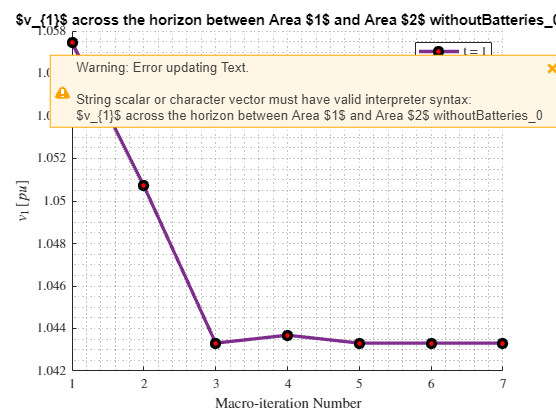

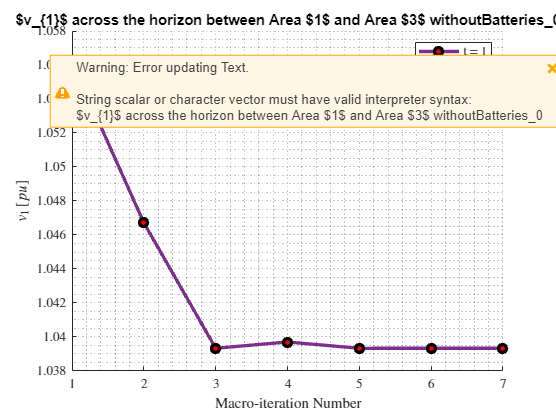

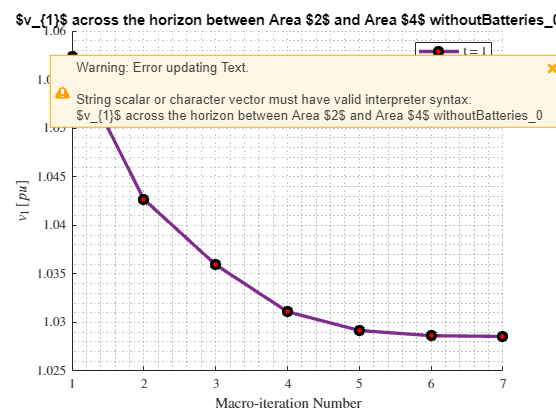

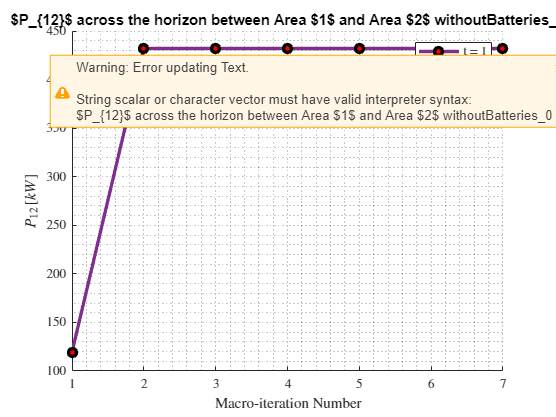

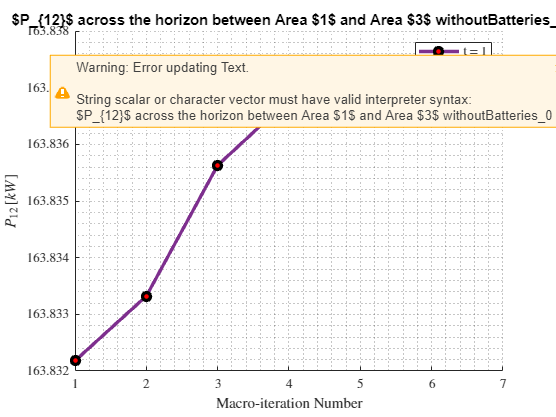

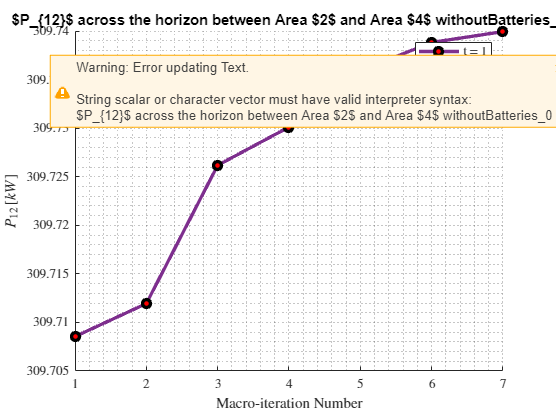

titleString = "$P_{Loss}$ across the horizon for the system using Spatially-Distributed-OPF withoutBatteries_0"

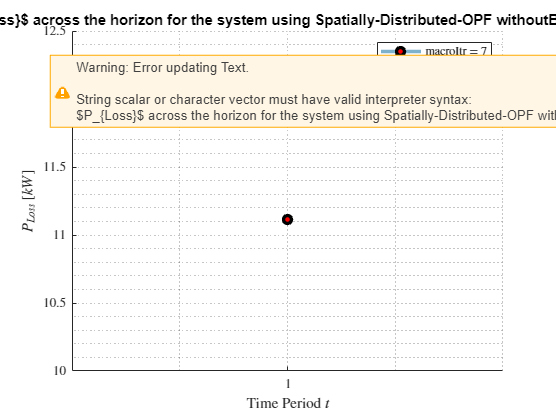

PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr(1:macroItr+1);
PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr(:, 1:macroItr+1);
PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr(1:macroItr+1);
PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr(:, 1:macroItr+1);
PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr(1:macroItr+1);
PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr(:, 1:macroItr+1);
v1_1toT_vs_macroItr = v1_1toT_vs_macroItr(:, :, 1:macroItr+1);
S12_1toT_vs_macroItr = S12_1toT_vs_macroItr(:, :, 1:macroItr+1);
P12_1toT_vs_macroItr = real(S12_1toT_vs_macroItr);
time_dist = time_dist(1:macroItr+1, :);

results = struct();
results.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;
results.PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
results.PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr;
results.PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr;
results.PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr;
results.PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr;
results.v1_1toT_vs_macroItr = v1_1toT_vs_macroItr;
results.S12_1toT_vs_macroItr = S12_1toT_vs_macroItr;


results.P12_1toT_vs_macroItr = P12_1toT_vs_macroItr;
% plot_relationships_over_time(results, simInfo, sysInfo)
plot_simulation_results(results, simInfo, sysInfo)

grandTotalTime = toc(start)

grandTotalTime = 89.2215

    
lineLoss_kW = 0;
genCost_dollars = 0;

for areaNum = 1:numAreas
    areaInfo = sysInfo.Area{areaNum};
    lineLoss_Area_kW = areaInfo.PLoss_allT * kVA_B;
    lineLoss_kW = lineLoss_kW + lineLoss_Area_kW;

    genCost_Area_dollars = areaInfo.PSubsCost_allT * 1e-2;
    genCost_dollars = genCost_dollars + genCost_Area_dollars;

end
area1Info = sysInfo.Area{1};

substationPower_kW = sum(area1Info.P_Area_1toT(1, :))*kVA_B;

maxTimes_vs_macroItr = max(time_dist, [], 2);
time_if_parallel = sum(maxTimes_vs_macroItr);
time_if_serial = sum(sum(time_dist));

if ~copf
    simNatureStringFull = strcat(simNatureString, " with ", num2str(numAreas), " Areas.");
else
    simNatureStringFull = simNatureString;
end

disp('------------------------------------------------------------')

------------------------------------------------------------


disp(['Machine ID: ', getenv("COMPUTERNAME")])

Machine ID: ETRL204-ARYAN


disp(['Horizon Duration: ', num2str(T)])

Horizon Duration: 1


disp(['Nature of Simulation: ', simNatureStringFull])

    "Nature of Simulation: "    "Spatially-Distributed-OPF with 4 Areas."



disp(['Line Loss: ', num2str(lineLoss_kW),' kW'])                       

Line Loss: 11.1121 kW


disp(['Substation Power: ', num2str(substationPower_kW),' kW'])

Substation Power: 767.1809 kW


disp(['Substation Power Cost: ', num2str(genCost_dollars), ' $'])

Substation Power Cost: 58.5475 $


disp(['Number of Macro-Iterations: ', num2str(macroItr)])

Number of Macro-Iterations: 6


disp(['Simulation Time: ', num2str(grandTotalTime), ' s'])

Simulation Time: 89.2215 s


disp(['Time to solve with sequential (non-parallel) computation: ', num2str(time_if_serial), ' s'])

Time to solve with sequential (non-parallel) computation: 79.185 s


disp(['Time to solve if OPF computation paralellized: ', num2str(time_if_parallel), ' s'])

Time to solve if OPF computation paralellized: 37.7202 s


disp('------------------------------------------------------------')

------------------------------------------------------------


% Assuming sysInfo, numAreas, T, and noBatteries are already defined in your workspace

% Construct the folder and file names
folderName = fullfile('processedData', sysInfo.systemName, strcat('numAreas_', num2str(numAreas), "/"));
prefixName = strcat(folderName, strcat('Horizon_', num2str(T)));
% systemSolutionName_x = strcat(prefixName, '_optimalSolutions.csv'); % For CSV file

% Determine the string based on whether batteries are included
if ~noBatteries
    battstring = strcat('withBatteries_', num2str(DER_percent));
else
    battstring = 'withoutBatteries_0';
end

% Construct the full path for the TXT file
systemsSolutionName_fval = strcat(prefixName, "_", getenv('COMPUTERNAME'), '_results_', battstring, '.txt');

% Open the file for writing
fileID = fopen(systemsSolutionName_fval, 'w');

% Check if the file was opened successfully
if fileID == -1
    error('Failed to open file for writing.');
end

% Write the results to the file
fprintf(fileID, '------------------------------------------------------------\n');
fprintf(fileID, 'Machine ID: %s\n', getenv("COMPUTERNAME"));
fprintf(fileID, 'Horizon Duration: %d\n', T);
fprintf(fileID, 'Nature of Simulation: %s\n', simNatureStringFull);
fprintf(fileID, 'Line Loss: %.2f kW\n', lineLoss_kW);                       
fprintf(fileID, 'Substation Power: %.2f kW\n', substationPower_kW);
fprintf(fileID, 'Substation Power Cost: %.3f $\n', genCost_dollars);
fprintf(fileID, 'Number of Macro-Iterations: %d\n', macroItr);
fprintf(fileID, 'Simulation Time: %.2f s\n', grandTotalTime);
fprintf(fileID, strcat('Time to solve with sequential (non-parallel) computation: ', num2str(time_if_serial), ' s\n'));
fprintf(fileID, 'Time to Solve if OPF computation parallelized: %.2f s\n', time_if_parallel);
fprintf(fileID, '------------------------------------------------------------\n');

% Close the file
fclose(fileID);

% Display a message indicating that the results were saved
disp(['Results saved to ', systemsSolutionName_fval]);

    "Results saved to "    "processedData\ieee123\numAreas_4\Horizon_1_ETRL204-ARYAN_results_withoutBatteries_0.txt"

